clear all; clc;

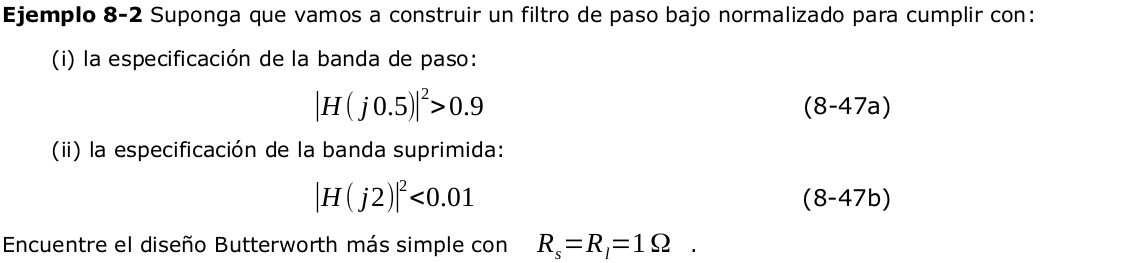

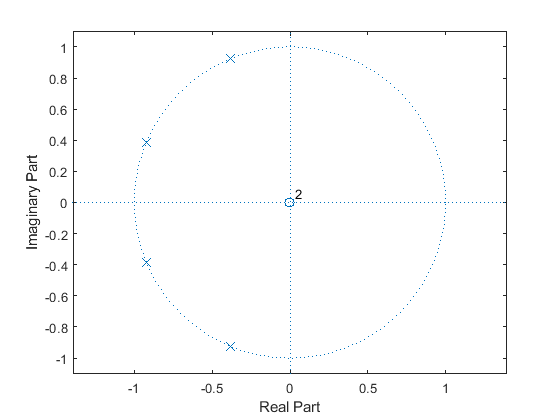


syms w 'real'
syms n 'integer'

%% datos del problema
Rl=1;
Rs=1;
atPaso=sym('0.9');
wPaso=sym('1/2');
atRechazo=sym('0.01');
wRechazo=sym('2');

%% función de transferencia propuesta
H2(w) = 1/(1+w^(2*n));

%% determinando el orden requerido
n1=vpasolve(H2(wPaso)==atPaso,n);
n1=ceil(n1);
n2=vpasolve(H2(wRechazo)==atRechazo,n);
n2=ceil(n2);
n=n2;
if n1>n
    n=n1;
end

%% determinando la H(s) según el orden
syms s K;
syms K 'real';
syms k 'integer';
H(s)=symprod(K/(s^2 + 2*sin((2*k-1)/(2*n)*pi)*s + 1), k, 1, n/2);
[B,A]=numden(vpa(collect(vpa(H(s),3)),3));
N=sym2poly(collect(B));
M=sym2poly(collect(A));
RN=roots(N);
RM=roots(M);

% verifiando la simetría cuadrantal
zplane(RN,RM);


%% darlington
% ganancia según Rs y Rl
K1=solve(H(0)==Rl/(Rl+Rs),K);
H(s)=subs(H(s),K,K1(2))

$$H(s) = \frac{0.5000}{\left(s^{2}+0.7654\,s+1\right)\,\left(s^{2}+1.8478\,s+1\right)}$$


% modulo al cuadrado del coeficiente de reflexión
rho2(s) = 1 - 4*H(s)*H(-s)

$$rho2(s) = 1-\frac{1}{\left(s^{2}-0.7654\,s+1\right)\,\left(s^{2}+0.7654\,s+1\right)\,\left(s^{2}-1.8478\,s+1\right)\,\left(s^{2}+1.8478\,s+1\right)}$$

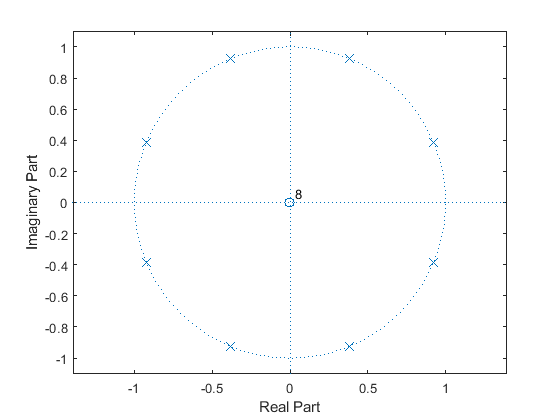

[B,A]=numden(collect(rho2(s)));
N=sym2poly(collect(B));
M=sym2poly(collect(A));
RN=roots(N);
RM=roots(M);

% verifiando la simetría cuadrantal visualmente

zplane(RN,RM);


% coeficiente de reflexión
rho(s)=collect(prod((s-RN(1:n))./(s-RM(1:n))));
[n,d]=numden(rho(s));
dp=sym2poly(d);
rho(s)=vpa(collect(n/dp(1))/collect(d/dp(1)),4)

$$rho(s) = \frac{1.0000\,s^{4}}{1.0000\,s^{4}+2.6131\,s^{3}+3.4142\,s^{2}+2.6131\,s+1.0000}$$


% posibles soluciones de la impedancia de entrada
Zin1(s)=(1-rho(s))/(1+rho(s));
Zin2(s)=(1+rho(s))/(1-rho(s));

% realización por cauer 1.
FLC(s)=Zin1(s);
vpa(collect(Zin1(s)),3)

$$ans = \frac{2.6131e+32\,s^{3}+3.4142e+32\,s^{2}+2.6131e+32\,s+1.0000e+32}{2.0000e+32\,s^{4}+2.6131e+32\,s^{3}+3.4142e+32\,s^{2}+2.6131e+32\,s+1.0000e+32}$$

clear k m;
m=1;
k=[];
while FLC(s)~=Inf
    FLC(s)=1/FLC(s);
    [n,d]=numden(collect(FLC(s)));
    np=sym2poly(n);
    dp=sym2poly(d);
    [r,p,k1]=residue(np,dp);
    if length(r)>0
        FLC(s)=sum( r(1:end)./(s-p(1:end)));
        k(m)=k1(1);
        m=m+1;
    else
        k(m)=k1(1);
        k(m+1)=k1(2);
        break;
    end
end
display(k)

k =     0.7654    1.8477    1.8483    0.7649    0.9995
